# Figure 1D

**Load Data**

[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = '..\..\FINAL DATA files';

load([dataDir filesep 'A001_data.mat'],'S','settings','allIF');
conditions = settings.conditions

conditions = 12×5 cell array
    {'siCtrl DMSO'      }    {[2 3 4]}    {[2 3]}    {[1]}    {[0 0 0]}
    {'siCtrl CDK1i'     }    {[2 3 4]}    {[4 5]}    {[1]}    {[0 0 0]}
    {'siCdh1 DMSO'      }    {[5 6 7]}    {[2 3]}    {[1]}    {[0 0 0]}
    {'siCdh1 CDK1i'     }    {[5 6 7]}    {[4 5]}    {[1]}    {[0 0 0]}
    {'siCtrl DMSO begin'}    {[2 3 4]}    {[  6]}    {[1]}    {[0 0 0]}
    {'siCtrl 4/6i begin'}    {[2 3 4]}    {[  7]}    {[1]}    {[0 0 0]}
    {'siCdh1 DMSO begin'}    {[5 6 7]}    {[  6]}    {[1]}    {[0 0 0]}
    {'siCdh1 4/6i begin'}    {[5 6 7]}    {[  7]}    {[1]}    {[0 0 0]}
    {'siCtrl starve'    }    {[2 3 4]}    {[  8]}    {[1]}    {[0 0 0]}
    {'siCtrl mock'      }    {[2 3 4]}    {[  9]}    {[1]}    {[0 0 0]}
    {'siCdh1 starve'    }    {[5 6 7]}    {[  8]}    {[1]}    {[0 0 0]}
    {'siCdh1 mock'      }    {[5 6 7]}    {[  9]}    {[1]}    {[0 0 0]}


 framesPerHr = 60/12;
 frameEdU = 0;
 timeStart = 0;
 folding =5;
 numFrames = size(S(1).area,2);
 xFrames = 1:numFrames;
 xTime = (xFrames-1)./framesPerHr;

 times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
 [S.POI_time] = times{:};

  for i = 1:length(S)
    
     S(i).POI_realtime = S(i).POI/framesPerHr;
  end

Proportion apc inact vs proportion s entry

conds = [1];
figure('units','inches','position',[0 0 4 8]), hold on

POI_align = 1;
POI_cal = 3;
data_out = [];
frames_out = [];
for i=1:length(conds)
    data = S(conds(i));
    inds = ~isnan(S(conds(i)).POI(:,POI_align))&...
        S(conds(i)).POI_realtime(:,1) <= 2& S(conds(i)).POI_realtime(:,1)>=0 ;
 
    event = data.POI(:,POI_cal);
    start = data.POI(:,1);
    ends = data.traceStats(:,6);

    y = event - start;
    lost = ends - start;
    y = y/framesPerHr;
    lost = lost/framesPerHr;
      censor = isnan(y);
    y(censor) = lost(censor);

    [f,x] = ecdf(y(inds),'Censoring',censor(inds));

     hold on
    plot(x,f,'LineWidth',1,'LineStyle','-','color',[.4 .6 1]);
  sum(inds)


   POI_cal = 2;

    event = data.POI(:,POI_cal);
  
    start = data.POI(:,1);
    ends = data.traceStats(:,6);

    y = event - start;
    lost = ends - start;
    y = y/framesPerHr;
    lost = lost/framesPerHr;
    
    censor = isnan(y);
    y(censor) = lost(censor);



[f,x] = ecdf(y(inds),'Censoring',censor(inds));

hold on

    plot(x,f,'LineWidth',1,'LineStyle','--','Color',[.2 0 .8]);
     
end

ans = 1441

ans = 1441

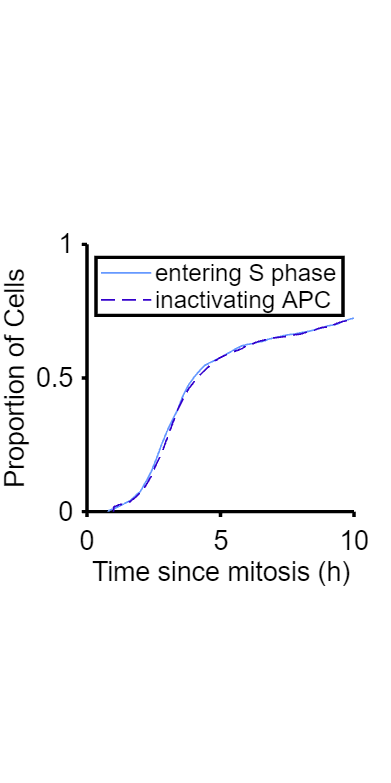

legend ('entering S phase','inactivating APC')
xlim([0 10])
ylim ([0 1])
xlabel('Time since mitosis (h)')
ylabel('Proportion of Cells')
axis square


% print_pdf('fig_1D.pdf')